# State of Charge Estimation

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

[⇦ Return to the Battery Management System menu](matlab:open('../FunctionLibrary/BatteryManagementSystem.mlx'))

In a daily basis, we are all used to check the battery level on our device powered by a battery. In some case, having battery means that we are still able to communicate, in other case it can our only way to get back home. In this course, you will learn how to develop the algorithm for a battery state of charge estimator.

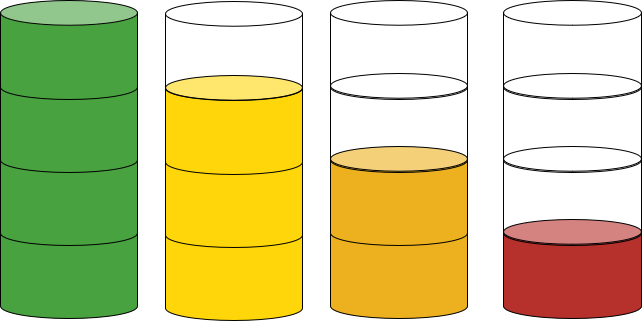

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction to State of Charge (SoC) Estimation

The State of Charge (SoC) of a battery is a measure of the remaining capacity of the battery, expressed as a percentage of its total capacity. SoC estimation is crucial for managing the operation and health of battery systems, especially in applications like electric vehicles (EVs) and renewable energy storage. Accurate SoC estimation helps in enhancing battery life, optimizing battery usage, and ensuring safety.

**Reflect.** Why is accurate SoC estimation important for battery management systems?

## Coulomb Counting

In [BatteryModeling.mlx](matlab:open('..\FunctionLibrary\BatteryModeling.mlx')), we developed a simple equivalent circuit model (ECM) for a lithium-ion battery used in EVs. We noted that the model is limited in its ability to simulate a full car ride because it fixes the voltage and the battery's internal resistance as constant. For a more practical simulation, the voltage and internal resistance should be functions of the battery. The fundamental method to estimate a battery's State of Charge is to monitor the current going through the battery to calculate the amount of charge lost or gained by the battery. The SoC is estimated with the following relationship:


$$ \text{SoC} = \text{SoC}_{\text{0}} -
 \frac{1}{3600C}\int i \, dt \qquad (1)$$


where $\text{SoC}$ is the current state of charge, $\text{SoC}_0$ is the initial state of charge, $C$ is the battery capacity in $\text{A}.\text{h}$ and $i$ is the current in $\text{A}$. With this relationship, the current is negative when the battery is discharging and positive when the battery is charging. In practice, State of Charge estimators are implemented on electronic chips using discrete methods. The continuous relationship $(1)$ can be approximated in discrete math by the following relationship:


$$\text{SoC}_{k+1} = \text{SoC}_k - \frac{T_s}{3600C}i \qquad (2)$$


where $\text{SoC}^{k+1}$ is the new State of Charge estimate, $\text{SoC}^k$ is the previous estimate, $T_s$ is the sampling time of the discrete method. $T_s$ represents the elapsed time in between two updates of the the State of Charge.

We are going to implement a Coulomb counting estimator for the same battery cell that was modeling in the [BatteryModeling.mlx](matlab:open('..\FunctionLibrary\BatteryModeling.mlx')) series. 

  **Try.** Load the battery cell data.

 
load(fullfile("Data","LiIonCell.mat"))
Datasheet = LiIon.Characteristic

We can select the sample time that will be used to update the state of charge for the rest of this script. By default, it is set to 1 second, but feel free to explore the impact of the sample time on our state estimator.

  **Try.** Select a sample time.

Ts = 1; % Sampling time (s)

if Ts > 5
    warning("You can continue with this large sample time, but the estimator might fail in some of the scenario considered later in this script.")
end
 

Similarly to our work in the [BatteryModeling.mlx](matlab:open('..\FunctionLibrary\BatteryModeling.mlx')) series, we will define a usage scenario for the battery. In this script, we will provide a function [CreateScenario.mlx](matlab:open('..\FunctionLibrary\CreateScenario.mlx')) that creates a usage scenario based on the user's input. The function returns a vector Time, Current, Voltage, and SoC (State of Charge). This SoC represents the real state of charge for the battery.

  **Try.** Use the live control below to define a usage scenario for the battery.

TotalTime = 3600;  % Total Time Simulation (s)
DischargeType = "Pulsed Discharge";    % Discharge profile (-)
DischargeCurrent = 1; % Maximum discharge current (A)

[Time,Current,Voltage,SoCi] = CreateScenario(FinalTime = TotalTime, SampleTime = Ts, ...
    Type = DischargeType, MaxCurrent = 1, ... % Maximum discharge current (A)
    AddNoise=true); % Add measurement noise
 


plot(Time,Current)
if DischargeType ~= "Continuous Discharge"
    ylim([min(Current)-0.05*range(Current) max(Current)+0.05*range(Current)])
end
grid on
ylabel("Current (A)")
xlabel("Time (s)")
xlim([0,TotalTime])

To implement Coulomb-counting, we need to define two parameters: the initial State of Charge ($\text{SoC}_0$) and the sampling time ($T_s$). 

 **Try.** The initial State of Charge is unknown, use the following slider to take a guess at what the initial SoC could be:

SoC0 = 0.6; % Initial State of Charge (0 - 100%)

 **Exercise.** Complete the code below to update the State of Charge estimate using Equation 2.

function SoC_kp1 = UpdateCoulomb(SoC_k,i,Ts,Q)

Datasheet = 101×16 table
    SoC      OCV        R0       OCV_20b    OCV_10b    OCV_0     OCV_25    OCV_40    OCV_60    R0_20b     R0_10b      R0_0       R0_25      R0_40      R0_60      dOCV 
    ____    ______    _______    _______    _______    ______    ______    ______    ______    _______    _______    _______    _______    _______    _______    ______

       0    2.5496    0.14748    2.5496     2.5496     2.5496    2.5496    2.5496    2.5496   


    % Modify the function body below to implement the equation 2:
    SoC_kp1 = 0;

end

 
CheckUpdateCoulomb(@UpdateCoulomb)

 **Exercise.** Complete code to run a simulation over `Time`.

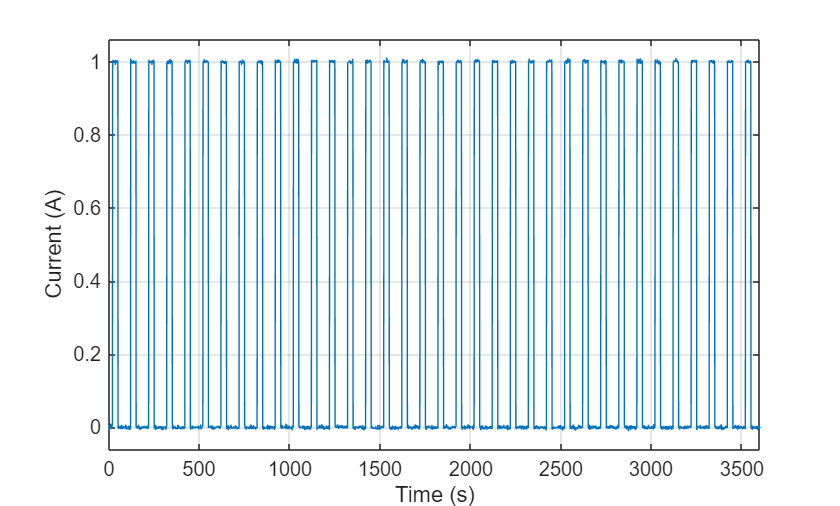

SoC = zeros(size(Time));

% Store initial value of SoC
SoC(1) = SoC0;

% Retrieve battery parameters:
C = LiIon.Capacity;

% Update SoC for 
for k = 2:length(Time)
    % This next line is currently not working, modify it to update the
    % state of charge correctly
    SoC(k) = 0; % Your code goes here
end

% Plot results
figure
plot(Time,SoC,DisplayName="SoC - Coulomb counting");
hold on
plot(Time,SoCi,DisplayName="SoC - Actual")
xlabel("Time (s)")
ylabel("State of Charge (-)")

grid on
set(gca,"YLimitMethod","padded")
CheckCoulombCounting(SoC,SoCi)

  **Try.** Re-run this simulation with different discharge scenario and different initial SoC.

 **Reflect.** Is Coulomb counting a viable option to estimate the State of Charge of a battery without knowing its initial SoC?

## Kalman filter

One limitation of Coulomb counting is that it is sensitive to noise in the voltage measurement. A Kalman filter is a mathematical method used to estimate the state of a system from a series of incomplete or noisy measurements. It is named after Rudolf Kálmán, one of the primary developers of its theory. The Kalman filter operates recursively on streams of noisy input data to produce a statistically optimal estimate of the underlying system state.

The working of a Kalman filter can be broken down into two main steps: prediction and update.

- Prediction: This step projects the current state estimate ahead of time. It uses the system's model to predict the state at the next time step and its uncertainty. This prediction is based on the system's known dynamics, such as its motion or process.

- Update: In this step, the Kalman filter incorporates the new measurement into the predicted state to refine its estimate. The filter calculates a weighted average of the expected state and the latest measurement, where the uncertainties of those estimates give the weights. The result is an updated estimate of the system's state and a reduced uncertainty estimate.

Kalman filters are used to estimate the state of charge (SoC) of a battery because they efficiently process noisy and uncertain measurements. Estimating the SoC of a battery is challenging because it cannot be measured directly and must be inferred from other observable quantities like voltage, current, and temperature. These measurements can be affected by noise and other inaccuracies.

Kalman filters are particularly useful in this context for several reasons:

- Accuracy: They can provide accurate estimates of the SoC by optimally combining multiple measurements over time, even if those measurements are noisy or incomplete.

- Real-Time Processing: Kalman filters are suitable for real-time applications because they operate recursively and can process each new measurement as it arrives.

- Adaptability: They can adapt to changes in the battery's characteristics over time, which is important for accurately estimating SoC throughout the battery's life.

 **Exercise.**  What metrics can be directly measured in a battery?

CheckMeasurable(...
    Temperature=true,...
    Voltage=true,...
    Capacity=false,...
    StateOfCharge=false,...
    Current=true,...
    CycleLife=false)
 

We can develop a model for the terminal voltage based on the terminal current and the known parameters of the batteries (Open Circuit Voltage, Internal resistance, Polarization resistance and capacitance), with the following relation:


$$V_\text{Terminal} = \text{OCV}(\text{SoC})-\tilde i\text{R}_0 - \text{V}_\text{pol}\\$$


where $V_\text{Terminal}$ represents the modeled terminal voltage, $\text{OCV}(\text{SoC})$ is the open circuit voltage as a function of the state of charge, $\tilde i$ is the measured current, $R_0$ is the internal resistance of the battery and $V_\text{pol}$ is the polarization voltage. The symbol $^\tilde$ denotes signals that are physically measured. For example, $\tilde V_\text{Terminal}$ represents the terminal voltage that is measured.

We can define the model error as:


$$V_\text{err} = V_\text{Terminal} - \tilde V_\text{Terminal}$$


We now have:

- Two measurements: $\tilde i$ and $\tilde V_\text{Terminal}$.

- A model: $V_\text{Terminal} = \text{OCV}(\text{SoC})-\tilde i\text{R}_0 - \text{V}_\text{pol}\\$.

- An estimate of the error: $V_\text{err} = V_\text{Terminal} - \tilde V_\text{Terminal}$.

Based on these elements, we are going to develop a Kalman filter to determine the State of Charge of the battery. The first step is to identify the model's unknowns that can not be measured, in our case, we know the internal resistance of the battery, the remaining unknowns are the State of Charge ($\text{SoC}$) of the battery and the polarization voltage ($\text{V}_\text{pol}$). We can define the battery state variable as:


$$x = \pmatrix{ \text{SoC} \cr \text{V}_\text{pol}  }$$


We define a function modeling the terminal voltage as a function of the battery characteristic ($\text{OCV}$,$\text{R}_0$), the battery state $x$ and the electrical current measured $\tilde i$.

function y = ModelTerminalVoltage(x,i_tilde,OCV,R0)

    % Retrieve Vpol from x
    Vpol = x(2);

    
    % Model the terminal voltage
    y = OCV - i_tilde*R0 - x(2);

end

In the rest of this script, we will develop a Kalman filter state estimator similar to the one included with [Simscape Battery](https://uk.mathworks.com/help/simscape-battery/ref/socestimatoradaptivekalmanfilter.html).

### Initialization

When we begin implementing a Kalman filter, the filter's initial state of charge and polarization voltage are unknown. Therefore, they need to be initialized. The successive prediction/correction steps should correct our initial guess and converge towards the battery's actual SoC and Vpol.

  **Try.** Define the initial State of Charge $\text{SoC}_0$ and polarization voltage$V_{\text{pol},0}$.

SoC0  = 0.8;
Vpol0 = 0;

if SoC0 < 0.1 || SoC0 > 1
    warning("We recommend that the initial guess for the state of charge be at least 10%.")
end
if Vpol0 < -0.2 || Vpol0 > 0.2
    warning("We recommend an initial polarization voltage of at most 0.2 V (in absolute value).")
end

% Create initial state
x = [SoC0; Vpol0]; % Define the initial battery state

### Prediction

In the prediction step, we are computing linearized Jacobian operator of the battery model


$$H = \pmatrix{\frac{d\text{OCV}}{d\text{SoC}} && 1}$$


function H = MatrixH(dOCV)
    H = [dOCV -1];
end


$$F = \pmatrix{1 & 0 \cr 0 & \exp(-\frac{T_s}{R_\text{pol}C_\text{pol}})}$$


function F = MatrixF(Ts,Rpol,Cpol)
    F = [1 0; 0 exp(-Ts/(Rpol*Cpol))];
end


$$G = \pmatrix{-\frac{T_s}{3600Q} \cr R_\text{pol}\left( 1 - \exp\left(\frac{T_s}{R_\text{pol}C_\text{pol} }\right) \right)}$$


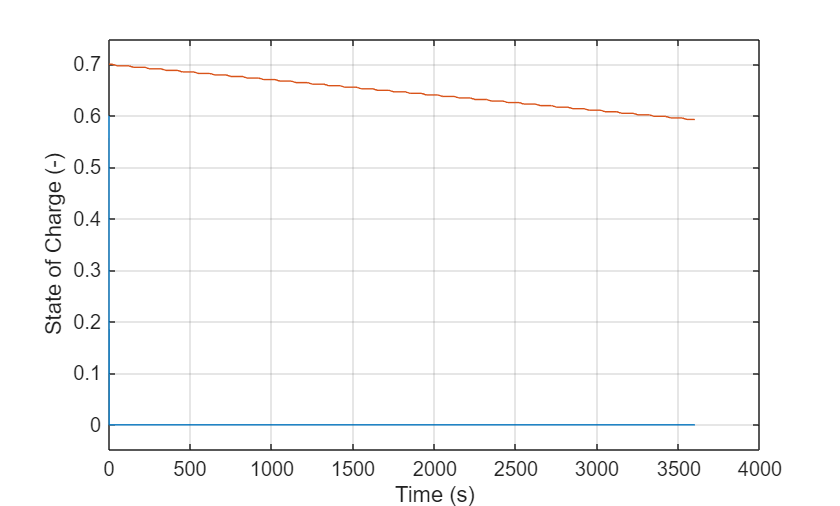

function G = MatrixG(Ts,C,Rpol,Cpol)
    G = [-Ts/(3600*C); Rpol*(1-exp(-Ts/(Rpol*Cpol)))];
end

Where $\frac{d\text{OCV}}{d\text{SoC}}$ is the derivative of the open circuit voltage with respect to the stage of charge, $T_s$ is the sample time, $C$ is the battery capacity in $\text{A.h}$, $R_\text{pol}$ and $C_\text{pol}$ are the polarization resistor and capacitor. All of those values can be retrieved from the constructor datasheet.

The state can be estimated using the following formula:

$x^{k+1} = Fx^{k}+Gi$,

where $x^{k+1}$ is the estimated state at the next step, $x^{k}$ is the current state of the battery.

 **Exercise.** Implement the new state prediction using the mathematical relation above.

function x_kp1 = PredictState(x_k,i,F,G)

    % Update State:
    x_kp1 = F*x_k + G*i;
end

CheckPredictKalman(@PredictState)

In order to be able to accurately correct this guess, we are need to estimate how "confident" we are in this guess. For that, we need to define the state estimator covariance $P$. Just like the battery state $x$, this metric is going to be updated at every iteration based on the previous value and the current error. We can update our guess for $P$ using the following relationship:


$$P^{i} = FP^{k}F^\top + Q$$


While $P$ represents the confidence in our state estimation, $Q$ is a parameter that models the process noise. It represents the how much we expect the battery state to vary in unpredictable ways. If we were to apply the Kalman filter not to battery state estimation but to trajectory tracking, the trajectory of an object could randomly vary based on external factors such as the wind, for example. This $Q$ parameter would represent how much random variability we are expecting in the path tracking based on those external factors. In the case of a battery, we are defining a $Q$ that represents the random variability of the battery state.

 **Exercise.** Implement the new state estimator covariance using the mathematical relation above.

function P_kp1 = PredictCovariance(P_k,F)
    
    % Define Q
    Q = [1e-4 0; 0 1e-4];

    % Update covariance:
    P_kp1 = 0;
end

CheckPredictCovariance(@PredictCovariance)

### Correction

In the correction step, we compute a Kalman gain:


$$K = (HP_{i}H+R)^{-1} P_{i}H'$$


With $R$ being the covariance of the measured noise, it represents how much error we expect to be introduced by our measurement. The Kalman gain is then used to update the battery state and covariance as follows:


$$x_{k+1} = x_{k}+KV_{err}\\
P_{k+1} = (I-KH)P_{k}$$


  **Try. Define the Kalman gain and correction step for** $x$ **and** $P$

function K = ComputeKalmanGain(P_k,H)
    % Define parameters:
    R = 0.7;

    % Compute Kalman Gain:
    K =  P_k*H' * inv(H*P_k*H' + R);

Good job! The easiest metrics to measure while a battery is operating are its temperature, voltage and current.


end

function x_kp1 = CorrectState(x_i,K,err)
    x_kp1 = x_i + K*err;
end

function P_kp1 = CorrectCovariance(P_i,K,H)
    P_kp1 = (eye(2)-K*H)*P_i;
end

### Implementation

Now that all the mathematical functions to implement the Kalman filter are complete and verified, we can implement a State of Charge estimator using a Kalman filter.

  **Try.** Explore and run the Kalman filter SoC estimator.

 
P0 = [1e-5 0;0 1];

% Declare vector storing all the SoC:
SoC = zeros(size(Time));

% Initialize the Kalman filter
Pk = P0;
SoC(1) = SoC0;
Vpol(1) = Vpol0;
Vp = 0;
xk = [SoC(1);Vpol(1)]; 

for k = 2:length(Time)

    % Compute batteries
    OCV = interp1(Datasheet.SoC,Datasheet.OCV,SoC(k-1));
    R0 = interp1(Datasheet.SoC,Datasheet.R0,SoC(k-1));
    dOCV = interp1(Datasheet.SoC,Datasheet.dOCV,SoC(k-1));
    Rpol = LiIon.Rpol;
    Cpol = LiIon.Cpol;
    C = LiIon.Capacity;

    % Compute Error and matrices:
    Vm = Voltage(k);
    Vt = ModelTerminalVoltage(x,Current(k),OCV,R0);
    Verr = Vm - Vt;

    % Compute matrices:
    H = MatrixH(dOCV);
    F = MatrixF(Ts,Rpol,Cpol);
    G = MatrixG(Ts,C,Rpol,Cpol);

    % Prediction
    xk = PredictState(xk,Current(k),F,G);
    Pk = PredictCovariance(Pk,F);

    % Correction
    if true
        K = ComputeKalmanGain(Pk,H);
        xk = CorrectState(xk,K,Verr);
        Pk = CorrectCovariance(Pk,K,H);
    end

    % Store SoC & Vpol
    SoC(k) = xk(1);
    Vpol(k) = xk(2);
end

tiledlayout(2,1)
nexttile
plot(Time,Current)
nexttile
plot(Time,SoC,DisplayName="SoC - Kalman")
hold on
plot(Time,SoCi,DisplayName="SoC - Actual")
legend
hold off

Good job! You define the prediction step correctly.


grid on
xlabel("Time (s)")
ylabel("State of Charge (-)")

**Reflect.** How different is the Kalman filter SoC estimator from Coulomb counting if the correction step is disabled?

## Further Exploration

### Link with BatteryModeling

The [CreateScenario.mlx](matlab:open('..\FunctionLibrary\CreateScenario.mlx')) function creates a battery usage scenario, with a certain electrical current profile and resulting terminal voltage. This function relies on the modeling method described in [BatteryModeling.m] coupled with a Coulomb counting State of Charge estimator ran with a very small sampling time. Explore this file to gain a better understanding of battery modeling.

### **Kalman filter video series**

Kalman filters are tools used to estimate the actual state of a system when the measurements are uncertain or indirect. They are particularly useful when you can only get indirect measurements of a system's state or noisy data from different sensors. Kalman filters combine this information to estimate the system's state best. This resource introduces Kalman filters through examples and basic math, helping learners understand how they work. It covers both basic Kalman filters and their nonlinear versions, like extended and unscented Kalman filters. It includes a practical example using MATLAB and Simulink to estimate the states of a linear system.

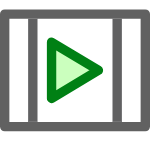 [Link to Kalman Filter video series](https://www.youtube.com/watch?v=mwn8xhgNpFY&list=PLn8PRpmsu08pzi6EMiYnR-076Mh-q3tWr)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

[⇦ Return to the Battery Management System menu](matlab:open('../FunctionLibrary/BatteryManagementSystem.mlx'))

## Helper functions

function CheckUpdateCoulomb(fun)
    s = rand;
    i = rand;
    t = rand;
    q = rand;

    sn = s - t/(3600*q)*i;
    if sn == fun(s,i,t,q)
        disp("Good job! You defined the Coulomb update step correctly")
    else
        warning("The function implementation should be an exact copy of the mathematical equation (2).")
    end

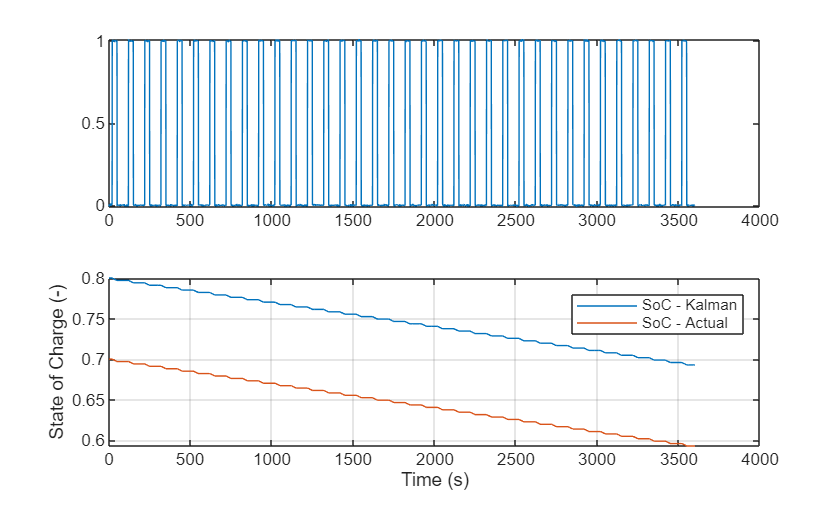


end

function CheckCoulombCounting(SoC,SoCi)
    cc = corrcoef(SoC,SoCi);
    if cc(1,2) < 0.8
        warning("SoC(k) should be replaced with SoC(k-1) in order to update the state of charge based on its previous value.")
    else
        disp("Good job! You modified the line correctly.")
    end
end

function CheckMeasurable(opts)
arguments
    opts.Temperature (1,1) logical
    opts.Voltage (1,1) logical
    opts.Capacity (1,1) logical
    opts.StateOfCharge (1,1) logical
    opts.Current (1,1) logical
    opts.CycleLife (1,1) logical
end

    err = false;
    if ~opts.Temperature
        warning("The temperature can be measured while the battery is operating.")
        err = true;
    end
    if ~opts.Voltage
        warning("The voltage can be measured while the battery is operating.")
        err = true;
    end
    if opts.Capacity
        warning("The capacity can not be measured while the battery is operating.")
        err = true;
    end
    if opts.StateOfCharge
        warning("The State of Charge can not be measured while the battery is operating.")
        err = true;
    end
    if ~opts.Current
        warning("The current can be measured while the battery is operating.")
    end
    if opts.CycleLife
        warning("The cycle life can not be measured while the battery is operating.")
        err = true;
    end

    if ~err
        disp("Good job! The easiest metrics to measure while a battery is operating are its temperature, voltage and current.")
    end
    
end

function CheckPredictCovariance(fun)
    P = rand(2);
    F = rand(2);
    G = rand(2,1);
    Q = [1e-4 0; 0 1e-4];
    
    try
        check = fun(P,F,G) == F*P*F'+Q;
    catch
        check = false;
    end

    if check
        disp("Good job! You define the prediction step correctly.")
    else
        warning("The implementation of the prediction should be identical to the mathematical relation above.")
    end
end


function CheckPredictKalman(fun)
    x = rand(2,1);
    i = rand;
    F = rand(2);
    G = rand(2,1);
    
    try
        check = fun(x,i,F,G) == F*x+G*i;
    catch
        check = false;
    end

    if check
        disp("Good job! You define the prediction step correctly.")

    else
        warning("The implementation of the prediction should be identical to the mathematical relation above.")
    end

end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

[⇦ Return to the Battery Management System menu](matlab:open('../FunctionLibrary/BatteryManagementSystem.mlx'))